# Assignment 1: classifiers

We now have some training data, corresponding labels, and a few test data to predict labels.

3 classifiers will be used, namely Bayes Decision Rule, Naïve Bayes, Linear discriminant analysis.

## Bayes Decision Rule:

Prior to everything, we import the data. And do some preprocessing.

clear
format long
load('label_train.mat', 'label_train');
load('data_train.mat', 'data_train');
load('data_test.mat', 'data_test');

[trainNumTotal, featureDim] = size(data_train);
[testNumTotal, featureDimTest] = size(data_test);
assert(featureDim==featureDimTest) %just do some validation

When coming to a question of classification, we need a disriminant function, Bayes told us that accroding to the Bayes Theory, one option of the function should be:


$$g_i \left(X\right)=\log \;p\left(X|\omega_i \right)+\log \;p\left(\omega_i \right)$$


the "prior probabilities" is much easier to retrieve

prior_positive = sum(label_train == 1) / trainNumTotal

prior_positive =    0.500000000000000


prior_negative = sum(label_train == -1) / trainNumTotal

prior_negative =    0.500000000000000


assert(prior_positive + prior_negative == 1)

as for the likelihood, we venture a guess that each class(class1 and class-1) consists of 2 Gaussian Distribution, we have a strong belief "大道至简" when building a model, but the "Simplicity" should be not the beginning but the end.

 the pdf(possibility density function) should be in a form of this:


$$p\left(\mathbf{X}|{\textrm{Class}}_1 \right)={\hat{\alpha} }_{11} N\left(\mathbf{X}|{\hat{\mu} }_{11} ,{\hat{\Sigma} }_{11} \right)+{\hat{\alpha} }_{12} N\left(\mathbf{X}|{\hat{\mu} }_{12} ,{\hat{\Sigma} }_{12} \right)$$



$$p\left(\mathbf{X}|{\textrm{Class}}_2 \right)={\hat{\alpha} }_{21} N\left(\mathbf{X}|{\hat{\mu} }_{21} ,{\hat{\Sigma} }_{21} \right)+{\hat{\alpha} }_{22} N\left(\mathbf{X}|{\hat{\mu} }_{22} ,{\hat{\Sigma} }_{22} \right)$$


where the Class1 denotes (1), class2 denotes(-1) in original data, just for alignment with the in-program ordinal.

class_num = 2;% when 2, binary classification.
components = zeros(class_num,1);
for indc = 1:class_num
    components(indc) = 2;% assume every class have 2 Gaussian
end
iter_limit = 1000;%the limitation of iteration
EM_stack = cell(iter_limit,1);%store all the iteration updated params.
EM = cell(class_num,max(components)*3);%current param group, update every epoch

for indi = 1:class_num
    for indj = 1:max(components)
        EM{indi, (indj-1)*3+1} = 1/components(indi); %assume all "a_hat" are equal in a class
        EM{indi, (indj-1)*3+2} = rand(featureDim,1).*5 - 2.5;%assume miu is random from -2.5 to 2.5
        sigmaTemp = rand(featureDim).*2 - 1;%assume covariance is random from -1 to +1, next step will double it
        sigmaTemp = sigmaTemp + transpose(sigmaTemp);
        sigmaTemp = transpose(sigmaTemp) * sigmaTemp;% this matrix should be positive definite matrix, I just guess ;)
        EM{indi, (indj-1)*3+3} = sigmaTemp;
    end
end
EM_stack{1,1} = EM;% 1st random param group

after the first step, we follow the procedure:

loop:

    estimate γ based on previous params;

    update params;

end

the formula is given as:


$$\gamma_{\textrm{ik}} \left(j\right)=p\left({\mathrm{G}}_i |{\mathbf{X}}_k \right)=\frac{p\left({\mathbf{X}}_k |{\mathrm{G}}_i \right){\hat{\alpha} }_i \left(j-1\right)}{\sum_{i=1}^m p\left({\mathbf{X}}_k |{\mathrm{G}}_i \right){\hat{\alpha} }_i \left(j-1\right)}$$



$$\begin{array}{l}
p\left({\mathbf{X}}_k |{\mathrm{G}}_i \right)=\;\\
\frac{1}{{2\pi }^{\frac{d}{2}} \sqrt{\left|{\hat{\Sigma} }_i \left(j-1\right)\right|}}\exp \left\lbrack -\frac{1}{2}{\left({\mathbf{X}}_k -{\hat{\mu} }_i \left(j-1\right)\right)}^T \;\;\;\;\;\;\;\;{\hat{\Sigma} }_i^{-1} \left(j-1\right)\;\;\;\;\left({\mathbf{X}}_k -{\hat{\mu} }_i \left(j-1\right)\right)\right\rbrack 
\end{array}$$


and param is :


$${\hat{\mu} }_i \left(j\right)=\frac{\sum_{k=1}^n \gamma_{\textrm{ik}} \left(j\right){\mathbf{X}}_k }{\sum_{k=1}^n \gamma_{\textrm{ik}} \left(j\right)}$$



$${\hat{\Sigma} }_i \left(j\right)=\frac{\sum_{k=1}^n \gamma_{\textrm{ik}} \left(j\right)\left\lbrack {\mathbf{X}}_k -{\hat{\mu} }_i \left(j\right)\right\rbrack {\left\lbrack {\mathbf{X}}_k -{\hat{\mu} }_i \left(j\right)\right\rbrack }^T }{\sum_{k=1}^n \gamma_{\textrm{ik}} \left(j\right)}$$



$${\hat{\alpha} }_i \left(j\right)=\frac{1}{n}\sum_{k=1}^n \gamma_{\textrm{ik}} \left(j\right)$$


Gamma_step = zeros(class_num,max(components),trainNumTotal);%store all gamma in current step
gamma_denominator = 0;
gamma_numerator = 0;

for j = 2:iter_limit %j is the iteration index
    for c = 1:class_num %deal with each class
        
        %calc the gamma
        for k = 1:trainNumTotal %calculate every sample
            if (label_train(k,1) == -1)&(c == 1)
                continue;
            end
            if (label_train(k,1) == 1)&(c == 2)
                continue;
            end
            gamma_denominator = 0;
            gamma_numerator = 0;
            for i = 1:components(c) %deal with each Gaussian components in this class
                %all param comes from previous EM
                EM = EM_stack{j-1,1};
                get_sigma = EM{c,3*i-0};
                get_miu = EM{c,3*i-1};
                get_alpha = EM{c,3*i-2};
                posibi_aa = (((2*pi)^(featureDim/2))*((det(get_sigma))^(0.5)))^(-1);
                cur_train = data_train(k,:)';
                posibi_bb = exp((-0.5)*(cur_train-get_miu)'*get_sigma*(cur_train-get_miu));
                posibi = posibi_aa*posibi_bb;
                gamma_numerator = posibi * get_alpha;
                gamma_denominator = gamma_denominator + gamma_numerator;
            end
            
            for i = 1:components(c)
                EM = EM_stack{j-1,1};
                get_sigma = EM{c,3*i-0};
                get_miu = EM{c,3*i-1};
                get_alpha = EM{c,3*i-2};
                posibi_aa = (((2*pi)^(featureDim/2))*((det(get_sigma))^(0.5)))^(-1);
                cur_train = data_train(k,:)';
                posibi_bb = exp((-0.5)*(cur_train-get_miu)'*get_sigma*(cur_train-get_miu));
                posibi = posibi_aa*posibi_bb;
                gamma_numerator = posibi * get_alpha;

                gamma_ = gamma_numerator/gamma_denominator;
                % my normalization process to the gamma, since some gamma is really small, while the counterpart is almost 1,
                % truncation error is introduced if I don't deal with it,
                % causing total probability greater than 1,
                % this is binary class problem, so I can deal in this way.
                if gamma_ < 1e-10
                    gamma_ = 0;
                elseif gamma_ >= (1-1e-10)
                    gamma_ = 1;
                end
                if i == 2
                    gamma_ = 1-Gamma_step(c,1,k);
                end

                Gamma_step(c,i,k) = gamma_;
            end
        end

        %%check gamma
        %for indkk = 1:210
            %assert(Gamma_step(1,1,indkk)+Gamma_step(1,2,indkk)==1)
        %end

        %update miu sigma alpha
        for i = 1:components(c)
            %miu
            miu_numerator = zeros(featureDim,1);
            miu_denominator = 0;
            for k = 1:trainNumTotal
                if (label_train(k,1) == -1)&(c == 1)
                    continue;
                end
                if (label_train(k,1) == 1)&(c == 2)
                    continue;
                end
                cur_train = data_train(k,:)';
                miu_numerator = miu_numerator + Gamma_step(c,i,k)*cur_train;
                miu_denominator = miu_denominator + Gamma_step(c,i,k);
            end
            EM_stack{j,1}{c,3*i-1} = miu_numerator/miu_denominator;
            
            %sigma
            sigma_numerator = zeros(featureDim);
            sigma_denominator = 0;
            for k = 1:trainNumTotal
                if (label_train(k,1) == -1)&(c == 1)
                    continue;
                end
                if (label_train(k,1) == 1)&(c == 2)
                    continue;
                end
                cur_train = data_train(k,:)';
                gamma_ = Gamma_step(c,i,k);
                EM = EM_stack{j,1};
                get_miu = EM{c,3*i-1};
                sigma_numerator = sigma_numerator + gamma_*(cur_train-get_miu)*transpose(cur_train-get_miu);
                sigma_denominator = sigma_denominator + gamma_;
            end
            EM_stack{j,1}{c,3*i} = sigma_numerator./sigma_denominator;

            %alpha
            alpha_ = 0;
            alpha_n = 0;
            for k = 1: trainNumTotal
                if (label_train(k,1) == -1)&(c == 1)
                    continue;
                end
                if (label_train(k,1) == 1)&(c == 2)
                    continue;
                end
                alpha_ = alpha_ + Gamma_step(c,i,k);
                alpha_n = alpha_n +1;
            end
            EM_stack{j,1}{c,3*i-2} = alpha_/alpha_n;

        end
    end
    
   % when we choose a large epoch number, select a graceful way to stop iteration 
   % it is rational to stop when parameters change very little
   bool_alpha = false;
   bool_miu = false;
   bool_sigma = false;
   diff_alpha = 0;
   diff_mean = 0;
   diff_cov = 0;

   for c = 1:class_num
       diff_alpha_ = abs((EM_stack{j,1}{c,1}-EM_stack{j-1,1}{c,1})/EM_stack{j-1,1}{c,1});
       diff_alpha = max(diff_alpha_,diff_alpha);
   end
   if diff_alpha < 0.000001
       bool_alpha = true;
   end

   for c = 1:class_num
       for i = 1:components(c)
           diff_mean_ = norm(EM_stack{j,1}{c,3*i-1}-EM_stack{j-1,1}{c,3*i-1});
           diff_mean = max(diff_mean_,diff_mean);
       end
   end
   if diff_mean < 0.000000001
      bool_miu = true;
   end

   for c = 1:class_num
       for i = 1:components(c)
           diff_cov_ = norm(EM_stack{j,1}{c,3*i}-EM_stack{j-1,1}{c,3*i});
           diff_cov = max(diff_cov_,diff_cov);
       end
   end
   if diff_cov < 0.000000001
       bool_sigma = true;
   end


   if bool_sigma & bool_miu & bool_sigma %break when all three parameters doesn't change
       break
   end
end
fprintf("finish %d iteration\r\n", j)

finish 1000 iteration



difference_1 = (EM_stack{iter_limit,1}{1,2}-EM_stack{iter_limit,1}{1,5})

difference_1 =   -0.061414297484584
  -0.018803708010457
   0.038407502154628
   0.070586849785931
   0.076636306459397


difference_2 = (EM_stack{iter_limit,1}{2,2}-EM_stack{iter_limit,1}{2,5})

difference_2 =   -0.036453862613993
  -0.068904775960547
   0.037680228101495
   0.003229482293218
   0.018792010398496


alpha_11 = EM_stack{iter_limit,1}{1,1}

alpha_11 =    0.528421199894185


alpha_12 = EM_stack{iter_limit,1}{1,4}

alpha_12 =    0.471578800105815


alpha_21 = EM_stack{iter_limit,1}{2,1}

alpha_21 =    0.469140884778194


alpha_21 = EM_stack{iter_limit,1}{1,4}

alpha_21 =    0.471578800105815


**After the EM algorithm, we need to check whether the hyperparameter "components(indc) = 2" is correct.**

**Eventually we find that difference between mean vector is quite small and proportion(alpha) is around 50%.**

**So it is persuasive for me to come to a conclusion that the train data only have one Gaussian Component in each class.**

**Since I write the code in a reusability manner, simply change the "components(indc) = 1" will lead to the final result of pdf(probability density function)**

%now only 1 Gaussian in each class, denoted by mean1 cov1,mean2 cov2
[mean1, mean2, cov1, cov2] = my_fit() %encapsulated into another .m file, for saving space

prior_positive =    0.500000000000000


prior_negative =    0.500000000000000


mean1 =    0.013795144447495
  -0.087557270747808
   0.084612565394574
  -0.154828836900726
   0.022750363405209


mean2 =    1.051708342806314
   1.799575418703208
   0.859564764127867
   1.064207535344899
   1.008554777370365


cov1 =    1.115087116177099   0.056201254885958  -0.004544547506340   0.028364280837793   0.050981687185565
   0.056201254885958   0.933969615554364   0.027432507080943  -0.041544732029383   0.075075906992944
  -0.004544547506340   0.027432507080943   0.848147569594492  -0.093544031624940   0.048987796417063
   0.028364280837793  -0.041544732029383  -0.093544031624940   0.941985196330820   0.077221592763229
   0.050981687185565   0.075075906992944   0.048987796417063   0.077221592763229   1.164002077320950


cov2 =    1.042761431504355   0.096980342198254  -0.039817958214805  -0.044078578309069   0.064821966132019
   0.096980342198254   0.835021893501854  -0.089766158204561   0.000986738077764  -0.077976526235769
  -0.039817958214805  -0.089766158204561   1.091985102761584   0.051127990998229   0.011184819932326
  -0.044078578309069   0.000986738077764   0.051127990998229   1.032829079596297   0.045676147862989
   0.064821966132019  -0.077976526235769   0.011184819932326   0.045676147862989   1.015583082722299


recap:


$$g_i \left(X\right)=\log \;p\left(X|\omega_i \right)+\log \;p\left(\omega_i \right)$$


we can finally get the result of test data:

label_test = zeros(testNumTotal,1);
for t = 1:testNumTotal
    p1_l = (2*pi*det(cov1))^-2;
    p1_r = exp((-0.5)*((data_test(t,:)'-mean1)')*cov1^(-1)*(data_test(t,:)'-mean1));
    p1 = p1_l*p1_r;
    g1 = log(p1) + log(prior_positive);

    p2_l = (2*pi*det(cov2))^-2;
    p2_r = exp((-0.5)*((data_test(t,:)'-mean2)')*cov2^(-1)*(data_test(t,:)'-mean2));
    p2 = p2_l*p2_r;
    g2 = log(p2) + log(prior_negative);

    if g1>g2
        label_test(t,1) = 1;
    elseif g1<g2
        label_test(t,1) = -1;
    else
        label_test(t,1) = 0;
    end
end
label_test

label_test =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


### Final Result of Bayes Decision Rule:

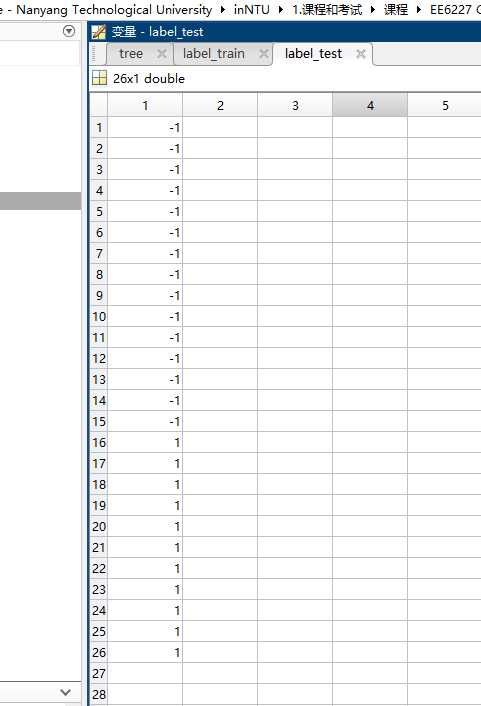

## Naïve Bayes:

also some preprocessing

clear
format long
load('label_train.mat', 'label_train');
load('data_train.mat', 'data_train');
load('data_test.mat', 'data_test');

[trainNumTotal, featureDim] = size(data_train);
[testNumTotal, featureDimTest] = size(data_test);
assert(featureDim==featureDimTest) %just do some validation

The principle of naive Bayes is based on the following beliefs:

Features are independent from each other.

this may not be true, but computational cheap.

the posterior probability is:


$$p\left(\omega_j |\mathbf{X}\right)=\frac{\prod_{i=1}^n p\left(x_i |\omega_j \right)p\left(\omega_j \right)}{p\left(\mathbf{X}\right)}$$


get prior first :)

prior_positive = sum(label_train == 1) / trainNumTotal

prior_positive =    0.500000000000000


prior_negative = sum(label_train == -1) / trainNumTotal

prior_negative =    0.500000000000000


assert(prior_positive + prior_negative == 1)

since the train data is continuous, we can assume that data follow Gaussian distribution. (Gaussian dist always have a dominant place among real world distributions)

for each feature, we have:


$$p\left(x|\omega_j \right)=\frac{1}{\sqrt{2\pi }\sigma_j }\exp \left(-\frac{1}{2}{\left(\frac{x-\mu_j }{\sigma_j }\right)}^2 \right)$$


we can use the maximum likelihood estimation.(intuitively, samples mean is dataset mean, std is dataset std)


% this question has no need to do with the reusability, directly obtain:
gaussian1_mean = (mean(data_train(1:210,1:5)))'

gaussian1_mean =    0.013795144447495
  -0.087557270747808
   0.084612565394574
  -0.154828836900726
   0.022750363405209


gaussian2_mean = (mean(data_train(211:420,1:5)))'

gaussian2_mean =    1.051708342806314
   1.799575418703210
   0.859564764127868
   1.064207535344899
   1.008554777370365


gaussian1_std = (std(data_train(1:210,1:5)))'

gaussian1_std =    1.058500099778256
   0.968730287384354
   0.923149875121612
   0.972878359577064
   1.081467274239362


gaussian2_std = (std(data_train(211:420,1:5)))'

gaussian2_std =    1.023596952247470
   0.915978828121292
   1.047477881325284
   1.018710383537627
   1.010169457032793



%also use the log dicriminant function
label_test = zeros(testNumTotal,1);
for t = 1:testNumTotal
    frac = 1;
    for f = 1:featureDimTest
        p1_l = ((2*pi)^(0.5)*gaussian1_std(f,1))^(-1);
        p1_r = exp((-0.5)*(((data_test(t,f)-gaussian1_mean(f,1))/gaussian1_std(f,1))^2));
        p1 = p1_l*p1_r;
        frac = frac * p1;
    end
    g1 = log(frac) + log(prior_positive);

    frac = 1;
    for f = 1:featureDimTest
        p2_l = ((2*pi)^(0.5)*gaussian2_std(f,1))^(-1);
        p2_r = exp((-0.5)*(((data_test(t,f)-gaussian2_mean(f,1))/gaussian2_std(f,1))^2));
        p2 = p2_l*p2_r;
        frac = frac * p2;
    end
    g2 = log(frac) + log(prior_negative);

    if g1>g2
        label_test(t,1) = 1;
    elseif g1<g2
        label_test(t,1) = -1;
    else
        label_test(t,1) = 0;
    end
end
label_test

label_test =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


### Final Result of Naive Bayes:

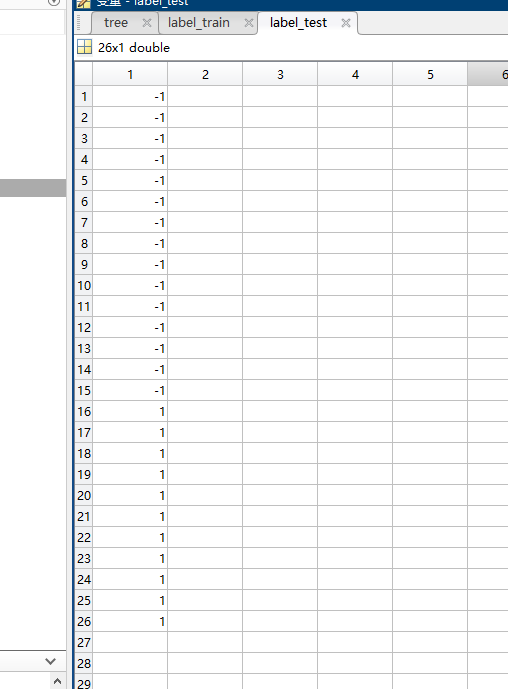

## LDA:

Bayes is not linear. So we need a method called LDA to build a linear classifier.

in hyperspace, construct a hyperplane(discrimination plane)


$$g\left(\mathbf{X}\right)={\mathbf{W}}^{\mathbf{T}} \mathbf{X}+w_0$$


How to get the W and w0?

Original thought is maximizing the interclass distance, and minimizing intraclass distance projected to the plane.

Finally we have:

- calc mean m1 and m2:   ${\mathbf{m}}_i =\frac{1}{n_i }\;\;\sum X$

- within class scatter mat: ${\mathbf{S}}_i =\sum \left(\mathbf{X}-{\mathbf{m}}_i \right){\left(\mathbf{X}-{\mathbf{m}}_i \right)}^{\mathrm{T}}$     ${\mathbf{S}}_w ={\mathbf{S}}_1 +{\mathbf{S}}_2$

- get W and w0: $\mathbf{w}={\mathbf{S}}_w^{-1} \left({\mathbf{m}}_1 -{\mathbf{m}}_2 \right)$  $w_0 =-\frac{{\mathbf{w}}^T \left({\mathbf{m}}_1 +{\mathbf{m}}_2 \right)}{2}$

- get g(X) and decide 1 when g(X)>0, or vice versa

clear
format long
load('label_train.mat', 'label_train');
load('data_train.mat', 'data_train');
load('data_test.mat', 'data_test');

[trainNumTotal, featureDim] = size(data_train);
[testNumTotal, featureDimTest] = size(data_test);
assert(featureDim==featureDimTest) %just do some validation

at this time, we introduce holdout method, so that we can have a quantitative perspective to evaluate the model.

data_train_new_class1 = data_train(1:200,1:5);
data_train_new_class2 = data_train(221:420,1:5);
data_test_for_score = data_train(201:220,1:5);

m1 = (sum(data_train_new_class1(:,:))/size(data_train_new_class1,1))';
m2 = (sum(data_train_new_class2(:,:))/size(data_train_new_class2,1))';

S1 = zeros(featureDim);
S2 = zeros(featureDim);
for k = 1:size(data_train_new_class1,1)
    S1 = S1 + (data_train_new_class1(k,:)'-m1)*transpose((data_train_new_class1(k,:)'-m1));
    S2 = S2 + (data_train_new_class2(k,:)'-m2)*transpose((data_train_new_class2(k,:)'-m2));
end
S = S1 + S2

S = 1.0e+02 *

   4.352847339287766   0.316876837615307  -0.055694676459105  -0.007153436365613   0.222020582058005
   0.316876837615307   3.589503892405840  -0.148801123543024  -0.074363628523358  -0.008060365514482
  -0.055694676459105  -0.148801123543024   3.897854165984334  -0.083074955509653   0.184635659173404
  -0.007153436365613  -0.074363628523358  -0.083074955509653   3.995162775755257   0.224109472946915
   0.222020582058005  -0.008060365514482   0.184635659173404   0.224109472946915   4.408573091685250


W = inv(S)*(m1-m2)

W =   -0.001973484807389
  -0.005214878912134
  -0.002191480831321
  -0.003058285812415
  -0.001945267696343


w0 = -(W'*(m1+m2))/2

w0 =    0.008941835556271


now we have the model, use the F1-Score to measure the model:

tp = 0;
fp = 0;
tn = 0;
fn = 0;
f1score = 0;

for t = 1:size(data_test_for_score,1)
    g = W'*data_test_for_score(t,:)' + w0;
    if g>0
        if label_train(200+t,1) ==1
            tp = tp+1;
        elseif label_train(200+t,1) ==-1
            fp = fp+1;
        end
    elseif g<0
        if label_train(200+t,1) ==1
            fn = fn+1;
        elseif label_train(200+t,1) ==-1
            tn = tn+1;
        end
    else
        assert(false);
    end
end
precision = tp/(tp+fp)

precision =    0.909090909090909


recall = tp/(tp+fn)

recall =      1


f1score = 2*precision*recall/(precision+recall)

f1score =    0.952380952380952


we can find the f1score is 0.952, pretty good XD

label_test = zeros(testNumTotal,1);
for t = 1:testNumTotal
    g = W'*data_test(t,:)' + w0;
    if g>0
        label_test(t,1) = 1;
    elseif g<0
        label_test(t,1) = -1;
    else
        label_test(t,1) = 0;
    end
end
label_test

label_test =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


### Final Result of LDA:

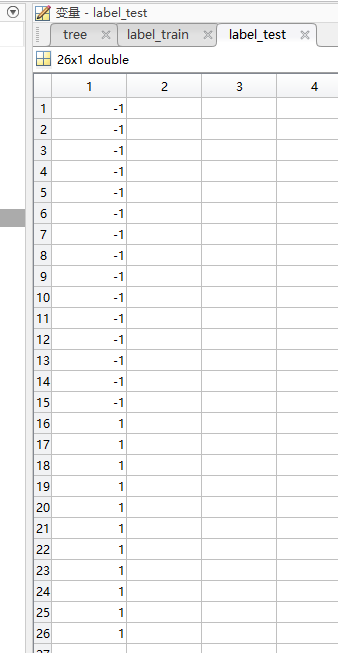

# Assignment 2: Nominal Data Classification

Unlike numeric data, nominal data is uncountable, so we can't calculate mean or covariance or determine the distance. So we use the classification tree.

## Binary Classification Tree:

Question 1: Are there any missing values and outliers in the training data? If there are, describe how you address the issues and explain the

rationale.

Answer: Yes, there are. I will discard them since I notice that only a few number of missing values and outliers, discarding them will hardly affect the dataset.

But when the number of unavailable values is large enough to affect model performance, we need methods such as interpolation/ mean filling. We will not discuss it here.

### Import data and preprocess:

clc
clear

opts = spreadsheetImportOptions;
opts.VariableTypes = 'double';
opts.MissingRule = 'omitrow';    %delete row contains missing val
opts.ImportErrorRule = 'omitrow';
opts.VariableNames = {'featureA','featureB','featureC','featureD','labelE'};
traintable = readtable('TrainingData.xlsx',opts);

outliers = isoutlier(traintable,"mean");
rowsToDelete = any(outliers == 1, 2);
traintable(rowsToDelete, :) = [];  %delete row contains outliers

### Build my tree:

when building a tree, most important thing is: test at each node leads to descendent "pure" nodes.

main procedures are:

- from root node, decide leaf nodes recursively, based on either impurity(entropy/ Gini/ etc.)

- set a threshold to terminate the splitting

- pruning (optional)

- assign leaf labels

as for the deriving of leaf nodes need a recursive routine, encapsulated in a class function, furthermore, some attributes need to maintain.

I will implement fitmytree in another .m file(also attached) since this .mlx only support POP rather than OOP.

features = traintable(:, {'featureA', 'featureB', 'featureC', 'featureD'});
labels = traintable.labelE;

mytree = fitmytree(features, labels, 1, 5); %3rd param is initial depth, 4th param is max limitation of depth.

### Predict:

% Load the test data
opts.VariableNames = {'featureA','featureB','featureC','featureD'};
testData = readtable('TestData.xlsx',opts);
testFeatures = testData(:, {'featureA', 'featureB', 'featureC', 'featureD'});

% Predict the labels of the test data

predictedLabels = inference(tree, testFeatures);

predictedLabels =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


### Final Result of Mytree:

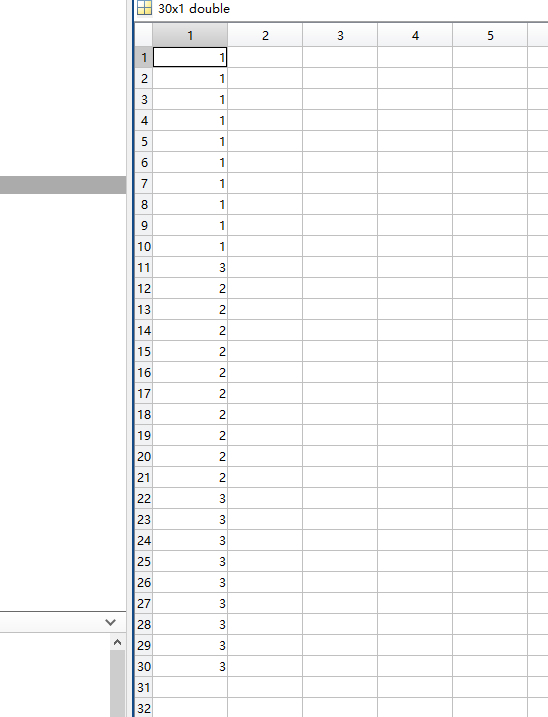

### Comparasion:

Using the intrinsic function of Matlab fitctree

clc
clear

opts = spreadsheetImportOptions;
opts.VariableTypes = 'double';
opts.MissingRule = 'omitrow';    %delete row contains missing val
opts.ImportErrorRule = 'omitrow';
opts.VariableNames = {'featureA','featureB','featureC','featureD','labelE'};
traintable = readtable('TrainingData.xlsx',opts);

outliers = isoutlier(traintable,"mean");
rowsToDelete = any(outliers == 1, 2);
traintable(rowsToDelete, :) = [];  %delete row contains outliers


features = traintable(:, {'featureA', 'featureB', 'featureC', 'featureD'});
labels = traintable.labelE;

% Train the binary classification tree
tree = fitctree(features, labels);

% Load the test data
opts.VariableNames = {'featureA','featureB','featureC','featureD'};
testData = readtable('TestData.xlsx',opts);
testFeatures = testData(:, {'featureA', 'featureB', 'featureC', 'featureD'});

% Predict the labels of the test data
predictedLabels = predict(tree, testFeatures)

predictedLabels =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


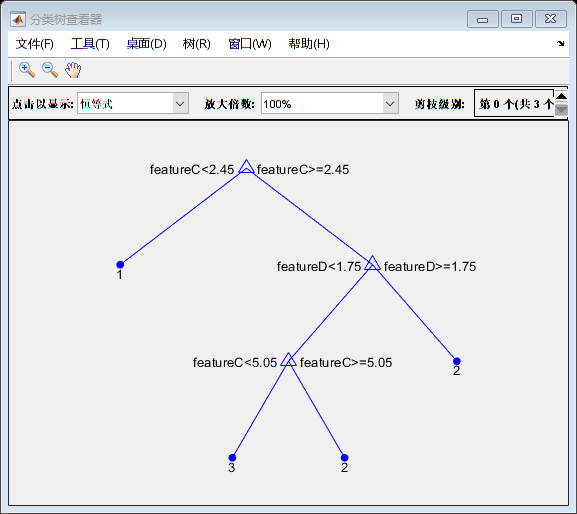

view(tree, 'Mode', 'graph')

### Final Result of Fitctree:

###